clc, clear, close all;
P=importdata(['D:\Users\jianz\Documents\MATLAB\Research_Projects\Data_Experiment_Proceed\' ...
    'P([R,G])_trajectories_dt=0.1548_Experimental_Pro_20241010_v1.mat']);
Lstack=importdata(['D:\Users\jianz\Documents\MATLAB\' ...
    'Lstack.mat']);
dt=0.1548;
h=2;
X = reshape(permute(P,[1,3,2]), [], 2);   % (nTraj*nFrames) x 2
% x in [0,100], y in [70,500], dx=2, dy=5
dxA = 2;  dyA = 5;
xA  = 0:dxA:100;
yA  = 70:dyA:500;
[XXA,YYA] = meshgrid(xA, yA);
x0A = [XXA(:), YYA(:)];
% Rectangle B: x in [0,400], y in [0,70], dx=5, dy=2
dxB = 5;  dyB = 2;
xB  = 0:dxB:400;    
yB  = 0:dyB:70;
[XXB,YYB] = meshgrid(xB, yB);
x0B = [XXB(:), YYB(:)];
% Combine into x0_all
x0_all = [x0A; x0B];

[mu, Sigma, info] = alg1_mu_sigma_2d(P, dt, h, x0_all, Lstack);


nx = numel(xB);
ny = numel(yB);
dx = dxB;
dy = dyB;
% Extract mu on B
nB = size(x0B,1);
nA = size(x0_all,1) - nB;
idxB = (nA+1):(nA+nB);
muB = mu(idxB,:); 
neffB = info.neff(idxB); 
% Reshape into grid arrays (rows correspond to y, cols correspond to x)
xB_pts = x0B(:,1);
yB_pts = x0B(:,2);
mask = (xB_pts >= 20) & (xB_pts <= 400) & (yB_pts >= 0) & (yB_pts <= 66);
muB_sub   = muB(mask,:);
neffB_sub = neffB(mask);
x0B_sub   = x0B(mask,:);
xB_sub = xB(xB >= 20 & xB <= 400);
yB_sub = yB(yB >= 0  & yB <= 66);
nx_sub = numel(xB_sub);
ny_sub = numel(yB_sub);
mu_r = reshape(muB_sub(:,1), ny_sub, nx_sub);
mu_g = reshape(muB_sub(:,2), ny_sub, nx_sub);
neff = reshape(neffB_sub,    ny_sub, nx_sub);
[ny, nx] = size(mu_r);
[XXB, YYB] = meshgrid(xB_sub, yB_sub); 

% ----- convert center mu -> MAC faces for hodge_poisson_faces -----
% mu_r_face: ny-by-(nx+1) on vertical faces
mu_r_face = zeros(ny, nx+1);
mu_r_face(:,2:nx)   = 0.5*(mu_r(:,1:nx-1) + mu_r(:,2:nx));
mu_r_face(:,1)      = mu_r(:,1);
mu_r_face(:,nx+1)   = mu_r(:,nx);

% mu_g_face: (ny+1)-by-nx on horizontal faces
mu_g_face = zeros(ny+1, nx);
mu_g_face(2:ny,:)   = 0.5*(mu_g(1:ny-1,:) + mu_g(2:ny,:));
mu_g_face(1,:)      = mu_g(1,:);
mu_g_face(ny+1,:)   = mu_g(ny,:);

% ----- Hodge decomposition (Poisson projection on MAC faces) -----
[phi, psi, h] = hodge_poisson_faces(mu_r_face, mu_g_face, dxB, dyB);

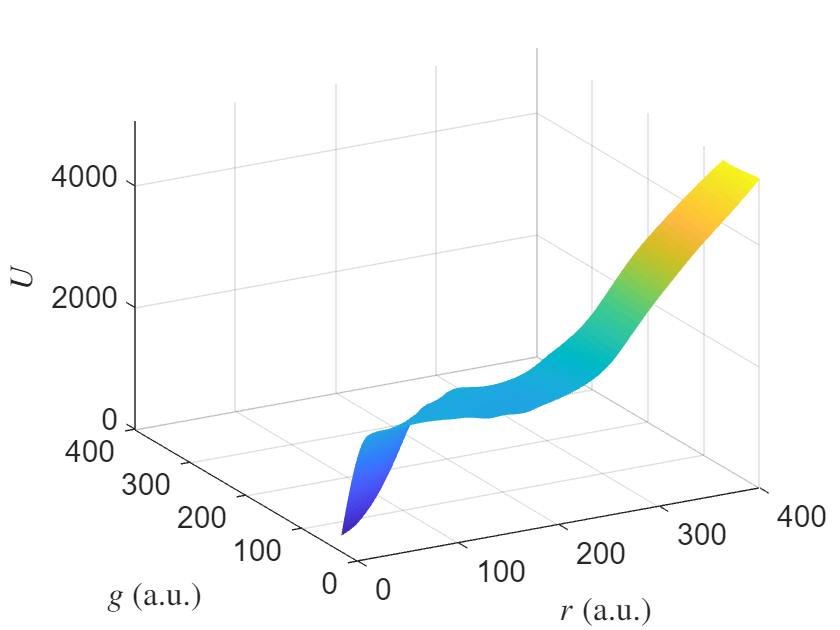

% Plot phi as landscape U
U = -phi;
U = U - min(U(:));

figure(1);
set(gcf,'Color','white');
surf(XXB, YYB, U, 'EdgeColor','none');
xlabel('$r$ (a.u.)','Interpreter','latex')
ylabel('$g$ (a.u.)','Interpreter','latex')
zlabel('$U$','Interpreter','latex')
xticks(0:100:400);
yticks(0:100:400);
zticks(0:2000:5000);
axis([0 400 0 400 min(U(:)) max(U(:))]);
view(-29,26);
set(gca,'fontsize',15);

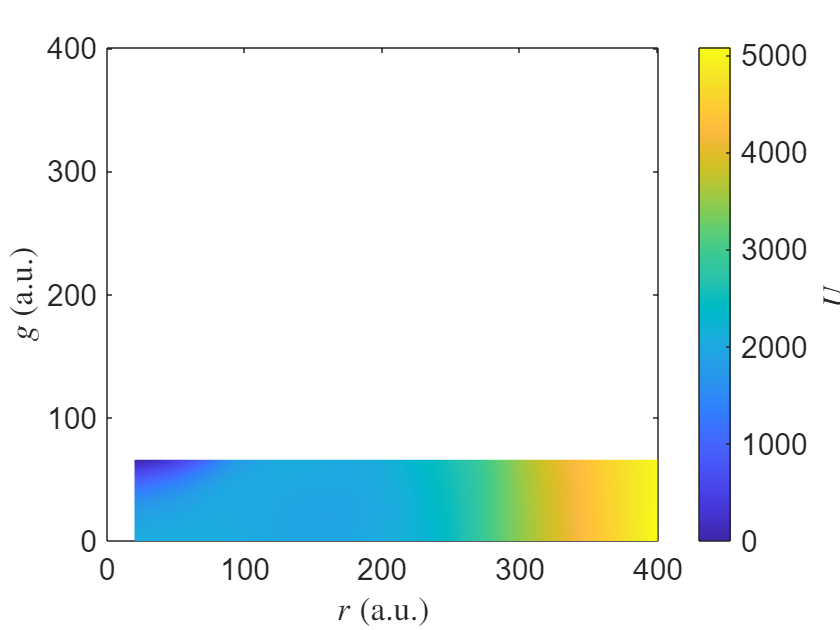

figure(2);
set(gcf,'Color','white');
pcolor(XXB, YYB, U);
shading interp;
cb = colorbar;
cb.Label.String = '$U$';
cb.Label.Interpreter = 'latex';
cb.FontSize = 15;
xlabel('$r$ (a.u.)','Interpreter','latex')
ylabel('$g$ (a.u.)','Interpreter','latex')
xticks(0:100:400);
yticks(0:100:400);
axis on;
axis([0,401,0,401]);
set(gca,'fontsize',15);

function [phi, psi, h] = hodge_poisson_faces(mu_r, mu_g, dx, dy)
%HODGE_POISSON_FACES  Discrete Hodge/Helmholtz decomposition on a uniform MAC grid.
%
% Input (MAC faces):
%   mu_r : ny-by-(nx+1)   x-component on vertical faces (x-faces)
%   mu_g : (ny+1)-by-nx   y-component on horizontal faces (y-faces)
%   dx,dy: grid spacing
%
% Output:
%   phi  : ny-by-nx       scalar potential at cell centers (gauge fixed)
%   psi  : ny-by-nx       stream function averaged to cell centers (for visualization)
%   h    : struct with face residual fields:
%          h.r : ny-by-(nx+1)
%          h.g : (ny+1)-by-nx
%
% Decomposition on faces:
%   mu = grad(phi) + perpgrad(psi_corner) + h
%
% Boundary conventions used here:
%   phi satisfies the natural Neumann condition implied by matching grad(phi) to mu on boundary faces.
%   psi_corner satisfies Dirichlet psi=0 on boundary corners, which makes the curl-projection unique.

    [ny, nxp1] = size(mu_r);
    [nyp1, nx] = size(mu_g);
    assert(nxp1 == nx+1, 'mu_r must be ny-by-(nx+1).');
    assert(nyp1 == ny+1, 'mu_g must be (ny+1)-by-nx.');

    ax = 1/dx^2;
    ay = 1/dy^2;

    idx = @(i,j) (j-1)*ny + i;      % cell-center indexing (column-major)
    N = ny*nx;

    % ---------------------------------------------------------------------
    % Step A: solve for phi on cell centers from Δphi = div(mu) with nonhomog Neumann
    % ---------------------------------------------------------------------
    div_mu = (mu_r(:,2:nx+1) - mu_r(:,1:nx))/dx + (mu_g(2:ny+1,:) - mu_g(1:ny,:))/dy;  % ny-by-nx
    b = div_mu(:);

    % Add non-homogeneous Neumann flux contributions induced by boundary face values.
    % These terms are essential when div_mu is (nearly) zero but boundary flux is not, e.g. mu=(x,-y).
    for i = 1:ny
        b(idx(i,1))  = b(idx(i,1))  + mu_r(i,1)/dx;        % left boundary
        b(idx(i,nx)) = b(idx(i,nx)) - mu_r(i,nx+1)/dx;     % right boundary
    end
    for j = 1:nx
        b(idx(1,j))  = b(idx(1,j))  + mu_g(1,j)/dy;        % bottom boundary
        b(idx(ny,j)) = b(idx(ny,j)) - mu_g(ny+1,j)/dy;     % top boundary
    end

    % Assemble discrete Laplacian Δ on cell centers with Neumann handled via ghost elimination.
    % Interior stencil: +ax neighbors, +ay neighbors, diagonal -(2ax+2ay).
    % Boundary cells: missing-neighbor effect adds +ax or +ay to the diagonal (reducing magnitude).
    I = zeros(5*N,1); J = zeros(5*N,1); V = zeros(5*N,1);
    t = 0;

    for j = 1:nx
        for i = 1:ny
            p = idx(i,j);

            diagc = -(2*ax + 2*ay);
            if j==1,  diagc = diagc + ax; end
            if j==nx, diagc = diagc + ax; end
            if i==1,  diagc = diagc + ay; end
            if i==ny, diagc = diagc + ay; end

            % left neighbor
            if j > 1
                t=t+1; I(t)=p; J(t)=idx(i,j-1); V(t)=ax;
            end
            % right neighbor
            if j < nx
                t=t+1; I(t)=p; J(t)=idx(i,j+1); V(t)=ax;
            end
            % bottom neighbor
            if i > 1
                t=t+1; I(t)=p; J(t)=idx(i-1,j); V(t)=ay;
            end
            % top neighbor
            if i < ny
                t=t+1; I(t)=p; J(t)=idx(i+1,j); V(t)=ay;
            end

            % center
            t=t+1; I(t)=p; J(t)=p; V(t)=diagc;
        end
    end

    L = sparse(I(1:t), J(1:t), V(1:t), N, N);

    % Gauge fixing to remove constant nullspace
    p0 = idx(1,1);
    L(p0,:) = 0;
    L(p0,p0) = 1;
    b(p0) = 0;

    phi_vec = L \ b;
    phi = reshape(phi_vec, ny, nx);

    % ---------------------------------------------------------------------
    % Step B: compute grad(phi) on faces with boundary faces matched to mu (Neumann convention)
    % ---------------------------------------------------------------------
    grad_r = zeros(ny, nx+1);
    grad_g = zeros(ny+1, nx);

    grad_r(:,2:nx) = (phi(:,2:nx) - phi(:,1:nx-1))/dx;
    grad_r(:,1)    = mu_r(:,1);
    grad_r(:,nx+1) = mu_r(:,nx+1);

    grad_g(2:ny,:) = (phi(2:ny,:) - phi(1:ny-1,:))/dy;
    grad_g(1,:)    = mu_g(1,:);
    grad_g(ny+1,:) = mu_g(ny+1,:);

    r_r = mu_r - grad_r;
    r_g = mu_g - grad_g;

    % ---------------------------------------------------------------------
    % Step C: solve for psi on corners via Δpsi = -curl(r), with psi=0 on boundary corners
    % ---------------------------------------------------------------------
    % psi_corner lives on (ny+1)-by-(nx+1) corner grid.
    % Define discrete curl of a face field at interior corners (i=2..ny, j=2..nx):
    %   curl(i,j) = ( r_g(i,j) - r_g(i,j-1) )/dx  -  ( r_r(i,j) - r_r(i-1,j) )/dy
    curl_corner = zeros(ny+1, nx+1);
    for j = 2:nx
        for i = 2:ny
            dv_dx = (r_g(i,j) - r_g(i,j-1))/dx;
            du_dy = (r_r(i,j) - r_r(i-1,j))/dy;
            curl_corner(i,j) = dv_dx - du_dy;
        end
    end

    % Solve Poisson on interior corners only, Dirichlet boundary psi=0.
    nyc = ny-1; nxc = nx-1;                 % number of interior corners in y/x
    Nc = nyc*nxc;
    idxc = @(ii,jj) (jj-1)*nyc + ii;        % interior-corner indexing, ii=1..ny-1, jj=1..nx-1

    I3 = zeros(5*Nc,1); J3 = zeros(5*Nc,1); V3 = zeros(5*Nc,1);
    b3 = zeros(Nc,1);
    t3 = 0;

    for jj = 1:nxc
        for ii = 1:nyc
            i = ii+1; j = jj+1;             % map to corner indices in full grid
            p = idxc(ii,jj);

            % Equation: Δpsi = -curl(r)
            b3(p) = -curl_corner(i,j);

            diagc = -(2*ax + 2*ay);

            if jj > 1
                t3=t3+1; I3(t3)=p; J3(t3)=idxc(ii,jj-1); V3(t3)=ax;
            end
            if jj < nxc
                t3=t3+1; I3(t3)=p; J3(t3)=idxc(ii,jj+1); V3(t3)=ax;
            end
            if ii > 1
                t3=t3+1; I3(t3)=p; J3(t3)=idxc(ii-1,jj); V3(t3)=ay;
            end
            if ii < nyc
                t3=t3+1; I3(t3)=p; J3(t3)=idxc(ii+1,jj); V3(t3)=ay;
            end

            t3=t3+1; I3(t3)=p; J3(t3)=p; V3(t3)=diagc;
        end
    end

    A3 = sparse(I3(1:t3), J3(1:t3), V3(1:t3), Nc, Nc);
    psi_int = A3 \ b3;

    psi_corner = zeros(ny+1, nx+1);
    for jj = 1:nxc
        for ii = 1:nyc
            psi_corner(ii+1, jj+1) = psi_int(idxc(ii,jj));
        end
    end

    % ---------------------------------------------------------------------
    % Step D: compute perpgrad(psi) exactly on faces from corner psi
    % ---------------------------------------------------------------------
    perp_r = zeros(ny, nx+1);
    perp_g = zeros(ny+1, nx);

    % x-component on vertical faces: dpsi/dy
    for j = 1:nx+1
        for i = 1:ny
            perp_r(i,j) = (psi_corner(i+1,j) - psi_corner(i,j))/dy;
        end
    end

    % y-component on horizontal faces: -dpsi/dx
    for j = 1:nx
        for i = 1:ny+1
            perp_g(i,j) = -(psi_corner(i,j+1) - psi_corner(i,j))/dx;
        end
    end

    % ---------------------------------------------------------------------
    % Step E: residual/harmonic term on faces and cell-centered psi for plotting
    % ---------------------------------------------------------------------
    h.r = mu_r - grad_r - perp_r;
    h.g = mu_g - grad_g - perp_g;

    % cell-centered psi for visualization (average of surrounding corners)
    psi = 0.25*(psi_corner(1:ny,1:nx) + psi_corner(2:ny+1,1:nx) + ...
               psi_corner(1:ny,2:nx+1) + psi_corner(2:ny+1,2:nx+1));
end





function [mu, Sigma, info] = alg1_mu_sigma_2d(P, dt, h, x0, Lstack)
%ALG1_MU_SIGMA_2D 2D extension of Algorithm-1 (simple method)
%
% Inputs
%   P   : nTraj x 2 x nFrames array. P(j,:,k) = [r,g] at frame k of traj j.
%   dt  : scalar. fixed time step between frames (here 0.1548).
%   W   : scalar. Gaussian kernel bandwidth in (r,g)-space.
%   x0  : nX0 x 2 array of query points where mu(x0), Sigma(x0) are evaluated.
%
% Outputs
%   mu     : nX0 x 2 array. mu(q,:) = [mu_r, mu_g] at x0(q,:).
%   Sigma  : 2 x 2 x nX0 array. Sigma(:,:,q) covariance-rate matrix at x0(q,:).
%   info   : struct with diagnostics (effective sample size, sum of weights).


    % Build sample pool: current positions X and increments dX across all traj & frames
    X  = P(:,:,1:end-1);              % nTraj x 2 x (nFrames-1)
    dX = diff(P, 1, 3);               % nTraj x 2 x (nFrames-1)

    % Reshape into (nSamples x 2)
    [nTraj, ~, nFrames] = size(P);
    nSteps   = nFrames - 1;
    nSamples = nTraj * nSteps;
    X  = reshape(permute(X,  [1,3,2]),  nSamples, 2);   % [traj,step,dim] -> rows
    dX = reshape(permute(dX, [1,3,2]),  nSamples, 2);

    % Preallocate outputs
    nX0 = size(x0,1);
    mu    = nan(nX0, 2);
    Sigma = nan(2, 2, nX0);

    % Constant factors: normalization of Gaussian kernel cancels in ratios,
    % but we keep the unnormalized exponential for numerical stability.
    inv2h2 = 1.0 / (2.0 * h * h);

    info.sumw = nan(nX0,1);
    info.neff = nan(nX0,1);

    % Main loop over query points
    for q = 1:nX0
        xq = x0(q,:);

        % 3.1) Gaussian kernel weights w_i = exp(-||z||^2/(2h^2)), z = L^{-1} (X - x0)
        Lq = Lstack(:,:,q);
        U  = X - xq;
        Zt = Lq \ U.'; 
        dist2 = sum(Zt.^2, 1).';
        w = exp(-dist2 * inv2h2);

        sw = sum(w);
        info.sumw(q) = sw;
        info.neff(q) = (sw*sw) / max(sum(w.^2), realmin);

        % If virtually no effective samples, leave NaN
        if sw <= 0 || info.neff(q) < 5
            continue;
        end

        % 3.2) mu(x0) = sum w * dX / (dt * sum w)
        mu_q = (w.' * dX) / (dt * sw);          % 1x2
        mu(q,:) = mu_q;

        % 3.3) 
        % Residual increments: dX - mu*dt
        % Sigma(x0) = (1/dt) * [ sum w * (R R^T) / sum w ]
        % Implement as weighted second moment: (R' * diag(w) * R)
        % without forming diag(w)
        R = dX - (dt * mu_q);                   % nSamples x 2
        RW = R .* sqrt(w);                      % nSamples x 2
        S = (RW.' * RW) / sw;                   % 2x2  (this equals sum w * R R^T / sum w)
        Sigma(:,:,q) = S / dt;                  % covariance-rate matrix

        % Enforce exact symmetry to remove roundoff asymmetry
        Sigma(:,:,q) = 0.5 * (Sigma(:,:,q) + Sigma(:,:,q).');
    end

    % Some additional diagnostics
    info.h  = h;
    info.dt = dt;
end